%Question 1)
A = sym([1 3;2 6]);
B = sym([3 -1;7 6]);
C = sym([1;2]);

2*A

$$ans = \left(\begin{array}{cc} 2 & 6\\ 4 & 12 \end{array}\right)$$

3*A+B

$$ans = \left(\begin{array}{cc} 6 & 8\\ 13 & 24 \end{array}\right)$$

A+C %should not be possible as dimensions dont match, however matlab makes it work

$$ans = \left(\begin{array}{cc} 2 & 4\\ 4 & 8 \end{array}\right)$$

A-B

$$ans = \left(\begin{array}{cc} -2 & 4\\ -5 & 0 \end{array}\right)$$

A*B

$$ans = \left(\begin{array}{cc} 24 & 17\\ 48 & 34 \end{array}\right)$$

B*A

$$ans = \left(\begin{array}{cc} 1 & 3\\ 19 & 57 \end{array}\right)$$

B^2 % is the same as B*B 

$$ans = \left(\begin{array}{cc} 2 & -9\\ 63 & 29 \end{array}\right)$$

B.^2 %squares every value in the matrix not the same as above

$$ans = \left(\begin{array}{cc} 9 & 1\\ 49 & 36 \end{array}\right)$$

%C^2 %cannot be done due to inner dimensions not matching
det(A)

$$ans = 0$$

%det(C) %not a square matrix, therefore no determinant
det(B)

$$ans = 25$$

transpose(A)

$$ans = \left(\begin{array}{cc} 1 & 2\\ 3 & 6 \end{array}\right)$$

transpose(C)

$$ans = \left(\begin{array}{cc} 1 & 2 \end{array}\right)$$

A+3*eye(2)

$$ans = \left(\begin{array}{cc} 4 & 3\\ 2 & 9 \end{array}\right)$$

A/B

$$ans = \left(\begin{array}{cc} -\frac{3}{5} & \frac{2}{5}\\ -\frac{6}{5} & \frac{4}{5} \end{array}\right)$$

%simultaneous equations
inv(B)*C

$$ans = \left(\begin{array}{c} \frac{8}{25}\\ -\frac{1}{25} \end{array}\right)$$

%question 2)
x = [2 2 3 4 4 2]; %declaring X coordinates
y = [0 2 3 2 0 0]; %declaring Y coordinates

S = [x;y]; %creating shape vector

%scaling vectors
%A = [0.9 0;0 0.9];
%A = [0.5 0;0 0.5];
%A = [-0.5 0;0 -0.5];
%A = [1 0;0 -1];
%A = [0.5 0;0 -0.5];
%A = [0 1;1 0];
%A = [0 1;-1 0];
%A = [0 -1;1 0];
%A = [cos(pi/3) -sin(pi/3);sin(pi/3) cos(pi/3)];
A = [cos(pi/6) -sin(pi/6);sin(pi/6) cos(pi/6)]

A =     0.8660   -0.5000
    0.5000    0.8660


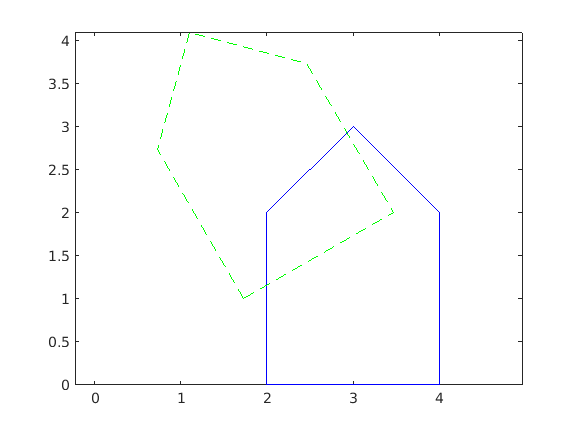



AS = A*S; %applying transformation

%setting new plot points
%selecting what needs to be returned by -> MATRIX(row,col) & :=all
xnew = AS(1,:); %selecing first row all columns
ynew = AS(2,:); %selecting second row all columns

%plotting
plot(x,y,"b") %plotting original "S" shape in blue
hold on %plotting on same graph
plot(xnew,ynew,"--g") %plotting transformed shape in green dotted line
axis equal %use same scale for both x & y axis
hold off 